%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ENG EC 503 (Ishwar) Fall 2023
% HW 4.4
% <Demetrios Kechris dkechris@bu.edu>
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% You are always welcome to vectorize your loop!

clear, clc, close all,

## 4.4 a) Normalization of data

disp("4.4a")

4.4a



% load data
load prostateStnd.mat

% calc train data norm vectors and apply to test data
% obtain mean and covariance of training data
%flip data to conform with dxn matrix size
disp("Transpose data to put it in Dxn format")

Transpose data to put it in Dxn format


Xtrain = Xtrain';
Xtest = Xtest';
ytrain = ytrain';
ytest = ytest';

meanX = XYmean(Xtrain);
meanY = mean(ytrain);
SX = Xcov(Xtrain);
SY = Xcov(ytrain);
disp("muX")

muX


disp(meanX)

   -0.0311
   -0.0538
    0.1189
   -0.0200
    0.0179
   -0.0250
   -0.0296
    0.0673



disp("muy")

muy


disp(meanY)

    2.4523



disp("SX")

SX


disp(SX)

    1.1063    0.3023    0.3028    0.0669    0.6312    0.7275    0.4392    0.5267
    0.3023    0.9167    0.3049    0.4212    0.1754    0.1501    0.0221    0.0736
    0.3028    0.3049    1.0107    0.2908    0.1312    0.1738    0.3603    0.2874
    0.0669    0.4212    0.2908    1.0130   -0.1417   -0.0891    0.0325   -0.0317
    0.6312    0.1754    0.1312   -0.1417    1.0244    0.6790    0.3042    0.5050
    0.7275    0.1501    0.1738   -0.0891    0.6790    0.9989    0.4663    0.6863
    0.4392    0.0221    0.3603    0.0325    0.3042    0.4663    0.9591    0.7685
    0.5267    0.0736    0.2874   -0.0317    0.5050    0.6863    0.7685    1.0743



disp("SY")

SY


disp(SY)

    1.4370



%mean_vec = 
%std_vec  =

% Normalize data:
ytrain_normalized = ytrain - meanY;
ytest_normalized  = ytest - meanY;

Xtrain_normalized = Xtrain - meanX;
Xtest_normalized = Xtest - meanX;

meanX_normalized = XYmean(Xtrain_normalized);
meanY_normalized = mean(ytrain_normalized);
SX = Xcov(Xtrain_normalized);
SY = Xcov(ytrain_normalized);

SXY = XYcov(Xtrain_normalized, ytrain_normalized);
SYX = XYcov(ytrain_normalized, Xtrain_normalized);


## 4.4 b) Train ridge regression model for various lambda (regularization parameter) values

disp("4.4b")

4.4b



xx = [-5:10];
lambda_vec = exp(xx);
coefficient_mat = zeros(size(Xtrain_normalized,1),length(lambda_vec));
% coefficient mat = Dxn matrix
% d = features
% n = lambda_vec length
% columns are each a w_ridge for the given lamdba_vec value

disp('Iterating through different lambdas...')

Iterating through different lambdas...


for i = 1:length(lambda_vec)
    coefficient_mat(:,i) = inv(diag(ones(size(coefficient_mat,1),1)*lambda_vec(i)) + SX) * SXY;
end
coefficient_mat

coefficient_mat =     0.6657    0.6491    0.6103    0.5340    0.4203    0.2935    0.1787    0.0920    0.0405    0.0161    0.0061    0.0023    0.0008    0.0003    0.0001    0.0000
    0.3026    0.3011    0.2967    0.2835    0.2504    0.1901    0.1170    0.0584    0.0250    0.0098    0.0037    0.0014    0.0005    0.0002    0.0001    0.0000
   -0.1375   -0.1322   -0.1190   -0.0903   -0.0433    0.0042    0.0253    0.0209    0.0109    0.0046    0.0018    0.0007    0.0002    0.0001    0.0000    0.0000
    0.2083    0.2069    0.2030    0.1926    0.1677    0.1239    0.0732    0.0350    0.0146    0.0056    0.0021    0.0008    0.0003    0.0001    0.0000    0.0000
    0.3009    0.2965    0.2858    0.2637    0.2274    0.1774    0.1184    0.0644    0.0291    0.0117    0.0045    0.0017    0.0006    0.0002    0.0001    0.0000
   -0.2725   -0.2497   -0.1980   -0.1058    0.0023    0.0698    0.0763    0.0498    0.0242    0.0100    0.0038    0.0014    0.0005    0.0002    0.0001    0.0000
   -0.0170   -0.


% b_ridge given the w_ridge column of coefficient_mat
% = 0 approx. since data is normalized
b_ridge = meanY_normalized  - (coefficient_mat' * meanX_normalized)

b_ridge = 1.0e-15 *

    0.1359
    0.1364
    0.1374
    0.1387
    0.1394
    0.1399
    0.1403
    0.1401
    0.1397
    0.1394


disp('4.4b Done.')

4.4b Done.


## 4.4 c) Plotting ridge regression coefficients

disp("4.4c")

4.4c


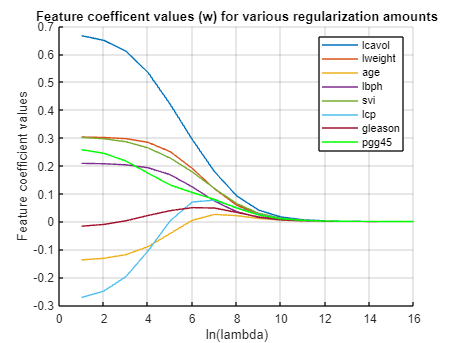


figure, grid on; hold on; xlabel('ln(lambda)'), ylabel('Feature coefficient values'); title('Feature coefficent values (w) for various regularization amounts')
mycolor = ["#0072BD" "#D95319" "#EDB120" "#7E2F8E" "#77AC30" "#4DBEEE" "#A2142F" "#00FF00"];
for i = 1:size(coefficient_mat,1)
    p = plot(coefficient_mat(i,:));
    p.Color = mycolor(i);
end
legend(names(1:8));
hold off

%Discuss what happens to the coefficients as λ becomes larger
    % as lambda increases, the value of lambda ||w||^2 
    % this means that larger values of w are penalized more heavily.
    % this promotes using a smaller value for w which is less complete (data wise). 
    % a precise answer using a complete w exists, but cannot be used
    % because of the penalty imposed.
    % the best CCR for the training will overfitting the data
    % large lambda penalty mitigates overfitting the data
    % small lambda penalty mitigates underfitting the data
    % i.e. a the smallest lambda will overfit the data, and the largest lambda
    % will underfit the data, leading to unoptimized test CCR on both sides
    % this is akin to the lambda constraint we used when implementing DP-centers

## 4.4 d) Plotting MSE values as function of ln(lambda)

disp("4.4d")

4.4d



%calculate w_ridge using lambda coefficient matrix
w_ridge = coefficient_mat

w_ridge =     0.6657    0.6491    0.6103    0.5340    0.4203    0.2935    0.1787    0.0920    0.0405    0.0161    0.0061    0.0023    0.0008    0.0003    0.0001    0.0000
    0.3026    0.3011    0.2967    0.2835    0.2504    0.1901    0.1170    0.0584    0.0250    0.0098    0.0037    0.0014    0.0005    0.0002    0.0001    0.0000
   -0.1375   -0.1322   -0.1190   -0.0903   -0.0433    0.0042    0.0253    0.0209    0.0109    0.0046    0.0018    0.0007    0.0002    0.0001    0.0000    0.0000
    0.2083    0.2069    0.2030    0.1926    0.1677    0.1239    0.0732    0.0350    0.0146    0.0056    0.0021    0.0008    0.0003    0.0001    0.0000    0.0000
    0.3009    0.2965    0.2858    0.2637    0.2274    0.1774    0.1184    0.0644    0.0291    0.0117    0.0045    0.0017    0.0006    0.0002    0.0001    0.0000
   -0.2725   -0.2497   -0.1980   -0.1058    0.0023    0.0698    0.0763    0.0498    0.0242    0.0100    0.0038    0.0014    0.0005    0.0002    0.0001    0.0000
   -0.0170   -0.0107    


%calculate b_ridge using w_ridge
b_ridge = meanY_normalized  - (w_ridge' * meanX_normalized )

b_ridge = 1.0e-15 *

    0.1359
    0.1364
    0.1374
    0.1387
    0.1394
    0.1399
    0.1403
    0.1401
    0.1397
    0.1394



MSE_train = zeros(1,size(coefficient_mat,2));
MSE_test = zeros(1,size(coefficient_mat,2));
for i = 1:size(MSE_train,2)
    MSE_train(i) = MSE(Xtrain_normalized,ytrain_normalized,w_ridge(:,i),b_ridge(i,1));
    MSE_test(i) = MSE(Xtest_normalized,ytest_normalized,w_ridge(:,i),b_ridge(i,1));
end
MSE_train

MSE_train =     0.4393    0.4399    0.4431    0.4573    0.4995    0.5937    0.7709    1.0161    1.2283    1.3492    1.4030    1.4242    1.4323    1.4353    1.4364    1.4368


MSE_test

MSE_test =     0.5820    0.5757    0.5630    0.5465    0.5382    0.5553    0.6299    0.7724    0.9120    0.9952    1.0327    1.0477    1.0534    1.0555    1.0563    1.0566


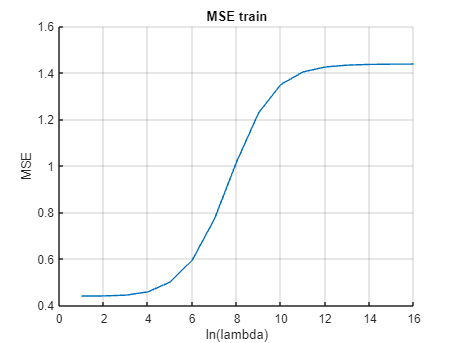

figure, grid on; hold on; xlabel('ln(lambda)'), ylabel('MSE'); title('MSE train')
plot(MSE_train)

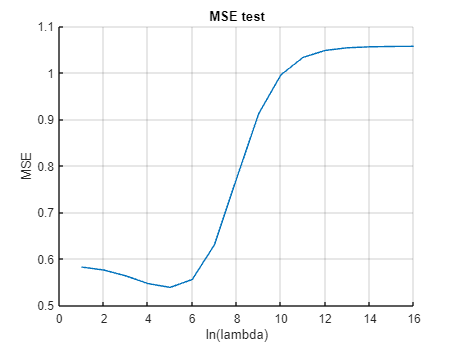

figure, grid on; hold on; xlabel('ln(lambda)'), ylabel('MSE'); title('MSE test')
plot(MSE_test)

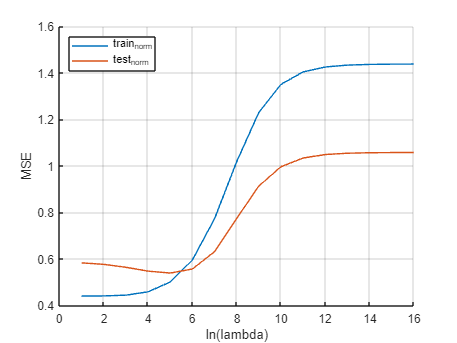

figure, grid on; hold on; xlabel('ln(lambda)'), ylabel('MSE');
plot(MSE_train)
plot(MSE_test)
legend({"train_norm","test_norm"},  'Location','northwest')


% Discuss your observations.
    % As stated in 4.4c, 
    % large lambda penalty mitigates overfitting the data
    % small lambda penalty mitigates underfitting the data
    % Overfitting the data (small lambda) will produce the best training
    % set results, but not the best test results
    % likewise, underfitting the data will produce poor training results,
    % and likely poor test results
    % the best choice will be somewhere in the middle, to prevent
    % overfitting and underfitting from occuring. 
    % Here we see ln(lambda_vec(5)) produces the lowest MSE on the test
    % data, and is the preferred lambda value to use. 

function MSE = MSE(data, label, w, b)
%takes in data, w, b and calcualtes the MSE
    MSE_array = zeros(1,size(data,2));
    for i = 1:size(data,2)
        MSE_array(i) = (label(i) - w'*data(:,i) - b)^2;
    end
    MSE = 1/(size(data,2))*sum(MSE_array);
end

## Helper functions from 4.3

function mean = XYmean(data)
% takes in an array of data (x1; x2; x3; ...)
% returns the mean of each column
    mean = zeros(size(data,1),1);
    for i = 1:size(data,1)
        Imean = sum(data(i,:))/size(data,2);
        mean(i,1) = Imean;
    end
end

function data_cov = Xcov(data)
% takes in an array of data (x1; x2; x3; ...)
% returns covariance of the data, dxd matrix
    mean = XYmean(data);
    data_norm = (data(:, :) - mean);
    data_cov = 0;
    for i = 1:size(data_norm,2)
        data_cov = data_cov + data_norm(:,i)*transpose(data_norm(:,i));
    end
    data_cov = data_cov / size(data_norm,2);
end

function data_cov = XYcov(data1,data2)
% takes in 2 arrays of data
% returns covariance of the data
    mean1 = XYmean(data1);
    mean2 = XYmean(data2);
    data1_norm = (data1(:, :) - mean1);
    data2_norm = (data2(:, :) - mean2);
    data_cov = 0;
    for i = 1:size(data1_norm,2)
        data_cov = data_cov + data1_norm(:,i)*transpose(data2_norm(:,i));
    end
    data_cov = data_cov / size(data1_norm,2);
end